clc
clear 
close all

%%
%--------------------------------------------------------------------------
% Data Generation 
%--------------------------------------------------------------------------

h= 5; k=6;
a= 1;
b= 1

b =      1

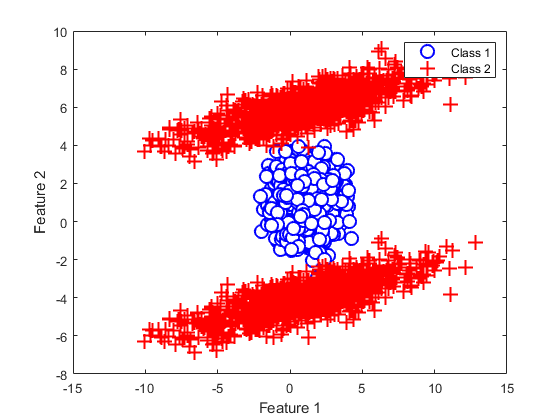

N = 1000;
xmin = 4;
xmax = 5;
%% convert in t-space
%tmin = acosh(xmin/a);
%tmax = acosh(xmax/a);
%% hyperbola computation
%t = linspace(-tmin,tmax,N);
x1 = a;
y1 = b;

x2 = a;
y2 = b;
  %NT = floor(N/10);
%x = 15+randn(N,2);
% figure, set(gcf,'color',[1 1 1])
% plot(x1,y1,'b-o','linewidth',3,'markersize',10,'markerfacecolor',[1 1 1])
% %hold on
% %plot(-x1,y1,'b-o','linewidth',3,'markersize',10,'markerfacecolor',[1 1 1])
% 
% plot(x2,y2,'r-+','linewidth',3,'markersize',10,'markerfacecolor',[1 1 1])
% %5hold on
% %plot(x2,-y2,'r-+','linewidth',3,'markersize',10,'markerfacecolor',[1 1 1])
% 

% xlabel('x coordinate','fontsize',18)
% ylabel('y coordinate','fontsize',18)
% set(gca,'fontsize',18)
%Best Regards.


%t=(1:N)*2*pi/N;
%t= t(:);

Sigma1 = [1 0; 0 1];
Sigma2 = [15 3; 3 1];
w_uncorr1 = randn(2*N,2);
w_corr1 = w_uncorr1*sqrtm(Sigma1);

w_uncorr2 = randn(N,2);
w_corr2 = w_uncorr2*sqrtm(Sigma2);

%plot( r*cos(t)+h, r*sin(t)+k);

figure;
% Visualization of the two classes (Toroid)
%z = [x+h+w_corr(:,1),y+k+w_corr(:,2)];
z1= [x1(:)+w_corr1(:,1), y1(:)+w_corr1(:,2)];
z21 = [x2(:)+w_corr2(:,1), y2(:)+h+w_corr2(:,2)];
z22 = [x2(:)+w_corr2(:,1), y2(:)-h+w_corr2(:,2)];
plot(z1(:,1),z1(:,2),'bo','LineWidth',1.5,'markersize',10,'MarkerFaceColor','w');
hold on
%plot(-z1(:,1),z1(:,2),'bo','LineWidth',1.5,'markersize',10,'MarkerFaceColor','w');
plot(z21(:,1),z21(:,2),'r+','LineWidth',1.5,'markersize',10,'MarkerFaceColor','w');
hold on
plot(z22(:,1),z22(:,2),'r+','LineWidth',1.5,'markersize',10,'MarkerFaceColor','w');

xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1','Class 2');




%z11 = z1;
%z12 = [-z1(:,1), z1(:,2)];
Z1 = z1;
%z21 = z2;
%z22 = [-z2(:,1), z2(:,2)];
Z2 = [z21; z22];

Z = [Z1; Z2];
T = [ones(size(Z1,1),1); 2*ones(size(Z2,1),1)];
trainingData = [Z T];
X=Z';
targ = zeros(size(T));
targ(T == 1) = 1;
t = targ';
